%Define network
net = network.IEEE68bus;
cellfun(@(b) b.component.set_avr(component.generator.avr.base), net.a_bus(1:16))
cellfun(@(b) b.component.set_pss(component.generator.pss.base), net.a_bus(1:16))
net.initialize


%コントローラレトロフィット
Q = [1, 1e8, 1];
R  = [1e-5, 1e8];

for i = 1:2
    con = controller.local_LQR(net,i,diag(Q),diag(R));
    net.add_controller_local(con);
end

%地絡応答でテスト
time = [0, 25];
fault = {{[1,1.05],1}};
out = net.simulate(time,'fault',fault);


 Simulation Start !!
 
0s                                                                                                25s
|        10%       20%       30%       40%       50%       60%       70%       80%       90%        |
|---------o---------o---------o---------o---------o---------o---------o---------o---------o---------|
|>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>|


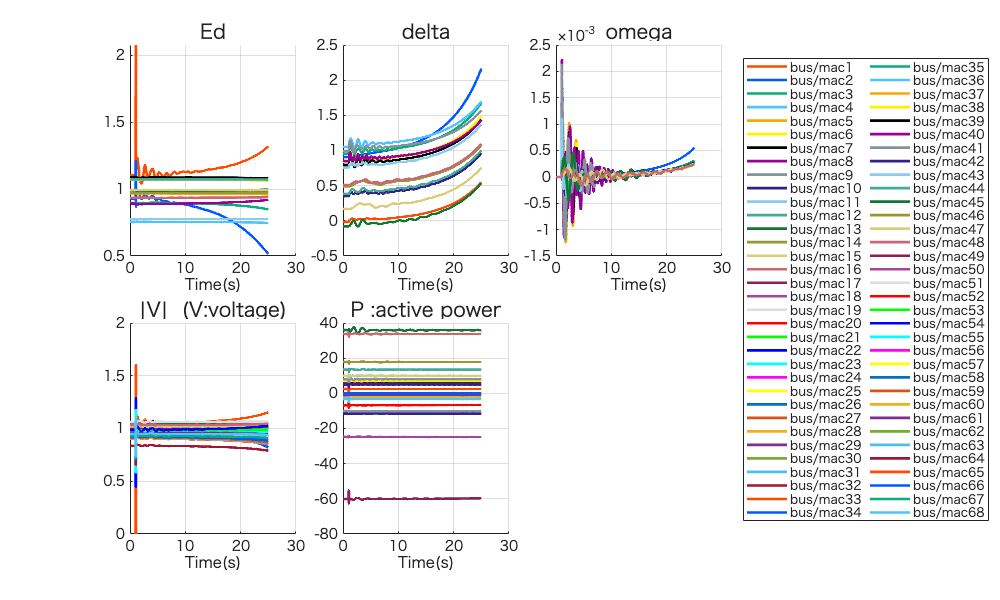

out.plot;
set(gcf,'Position',[0,0,1000,600])